Семинар 4.

## Тема: "Регуляризация по Годунову плохообусловленной системы"

**Задание:** Дискретизировать интегральное уравнение $\int_b^a K\left(s,t\right)x\left(t\right)\textrm{dt}=f\left(s\right),c\le s\le d$ и решить полученную СЛАУ применяя метод регуляризации по Годунову.

clc;
clear;

M = 11

M = 11

N = 21

N = 21

a = 0

a = 0

b = 1

b = 1

c = 0

c = 0

d = 1

d = 1


h_s = (b-a)/(M-1)

h_s = 0.1000

h_t = (d-c)/(N-1);

t = (a:h_t:b)'

t =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


s = (c:h_s:d)'

s =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000



A = zeros(N, M);
for i = 1:N
    %A(i, 1) = exp(t(i) - s(1));
    %A(i, M) = -exp(t(i) - s(M));
    for j = 1:M
        if j > 1
            A(i, j) = A(i, j) + ((s(j) - t(i))^3 - (s(j - 1) - t(i))^3)*((t(i) - s(j - 1))/(3*h_s)) + ...
                ((s(j) - t(i))^4 - (s(j - 1) - t(i))^4)/(4*h_s);
            %A(i, j) = A(i, j) + exp(t(i))*((exp(-s(j - 1)) - exp(-s(j))) / h_s);
        end
        if j < M
            A(i, j) = A(i, j) + ((s(j + 1) - t(i))^3 - (s(j) - t(i))^3)*((s(j + 1) - t(i))/(3*h_s)) + ...
                ((s(j) - t(i))^4 - (s(j + 1) - t(i))^4)/(4*h_s);
            %A(i, j) = A(i, j) + exp(t(i))*((exp(-s(j + 1)) - exp(-s(j))) / h_s);
        end
    end
end
mu = cond(A)

mu = 1.2620e+16


F = f2(t, a, b)

F =     0.1606
    0.1358
    0.1141
    0.0956
    0.0802
    0.0680
    0.0589
    0.0531
    0.0503
    0.0508


B = zeros(M, M);
for j = 1:M
    for i = 2:M-1
        if abs(i - j) == 0
            B(i, j) = -2/h_s^2;
        end
        if abs(i - j) == 1
            B(i, j) = 1/h_s^2;
        end
    end
end

%tau = 1/8*h_s^2 * 0.1;
tau = 0.0001

tau = 1.0000e-04

C = [(1 - tau).*A; tau.*B]

C =     0.0001    0.0012    0.0042    0.0092    0.0162    0.0252    0.0362    0.0492    0.0642    0.0812    0.0467
    0.0000    0.0004    0.0024    0.0064    0.0124    0.0204    0.0304    0.0424    0.0564    0.0724    0.0420
    0.0002    0.0002    0.0012    0.0042    0.0092    0.0162    0.0252    0.0362    0.0492    0.0642    0.0376
    0.0007    0.0004    0.0004    0.0024    0.0064    0.0124    0.0204    0.0304    0.0424    0.0564    0.0334
    0.0014    0.0012    0.0002    0.0012    0.0042    0.0092    0.0162    0.0252    0.0362    0.0492    0.0294
    0.0024    0.0024    0.0004    0.0004    0.0024    0.0064    0.0124    0.0204    0.0304    0.0424    0.0257
    0.0036    0.0042    0.0012    0.0002    0.0012    0.0042    0.0092    0.0162    0.0252    0.0362    0.0222
    0.0050    0.0064    0.0024    0.0004    0.0004    0.0024    0.0064    0.0124    0.0204    0.0304    0.0190
    0.0067    0.0092    0.0042    0.0012    0.0002    0.0012    0.0042    0.0092    0.0162    0.0252    0.01

cond(C)

ans = 57.0206

F_reg = [(1 - tau).*F; zeros(M, 1)]

F_reg =     0.1606
    0.1357
    0.1141
    0.0955
    0.0802
    0.0680
    0.0589
    0.0531
    0.0503
    0.0508


x_comp = C\F_reg

x_comp =     0.9893
    0.9055
    0.8228
    0.7435
    0.6698
    0.6036
    0.5454
    0.4947
    0.4497
    0.4081


x_real = true_x_2(s)

x_real =     1.0000
    0.9048
    0.8187
    0.7408
    0.6703
    0.6065
    0.5488
    0.4966
    0.4493
    0.4066


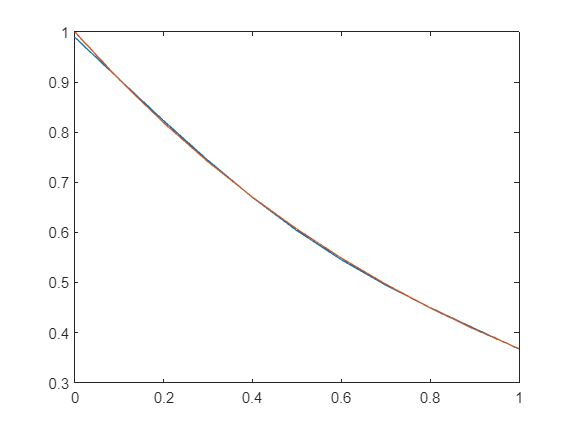


plot(s, x_comp)
hold on;
plot(s, x_real)
hold off;

function true_solution_1 = true_x_1(T)
    true_solution_1 = T.^2;
end

function true_solution_2 = true_x_2(T)
    true_solution_2 = exp(-T);
end

function K_first = K_1(t, s)
    K_first = exp(t - s);
end

function K_second = K_2(t, s)
    K_second = (t - s).^2;
end

function right_first = f1(S, a, b)
        right_first = (-(b^2 + 2*b + 2)*exp(-b) + (a^2 + 2*a + 2)*exp(-a))*exp(S);
end

function right_second = f2(S, a, b)
        right_second = exp(-a)*(S.^2 + (-2*a - 2).*S + a^2 + 2*a + 2)...
            - exp(-b)*(S.^2 + (-2*b - 2).*S + b^2 + 2*b + 2);
end